# **Figure3**

本code是第五稿重新画figure3的时候在原始处理碰撞数据的脚本的基础上整理出来的。

# **读入数据**

clear
clc
filepath1 = 'D:\work\散射场\实验数据\20220413_Au_Colission\Result\B1_reconstructed';
filepath2 = 'D:\work\散射场\实验数据\20220413_Au_Colission\TIFF\B1';
tiffs1 = dir(fullfile(filepath1,'*.*tif*'));
tiffs1 = struct_sort(tiffs1);
tiffs2 = dir(fullfile(filepath2,'*.*tif*'));
tiffs2(1:1250) = [];

# **对颗粒2作图**

**这里的颗粒2指的是'D:\work\散射场\实验数据\20220413_Au_Colission\Result\Particle_Intensity_Tracking.mat'文件夹里面rec/reconstructedData/spr/sprData里面第二列数据，对应下图中红框框住的颗粒：**

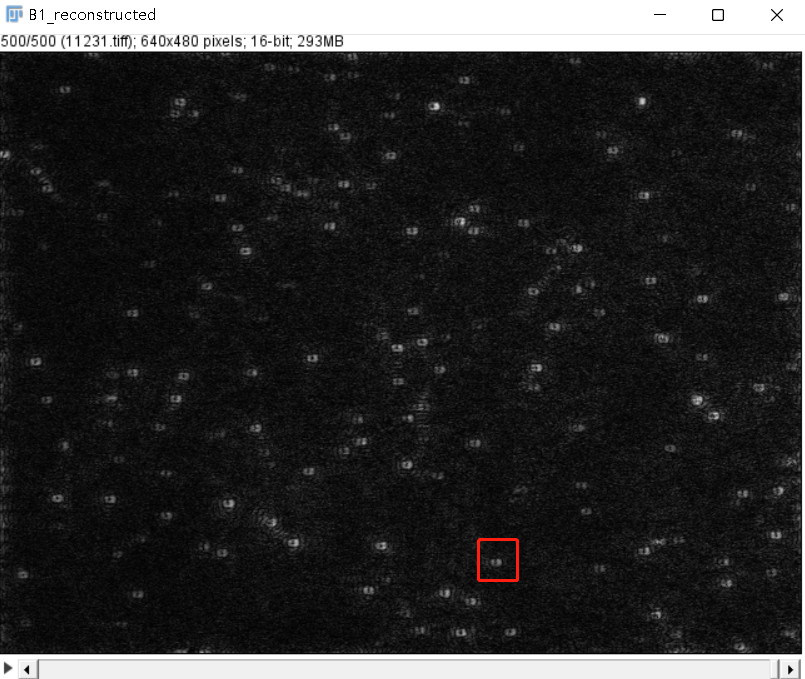

(the 10000th reconstructed frame).由于这个颗粒一直在视野中摆动，所以位置并不是一直不变的。

temp_tiff = double(imread(fullfile(filepath1,tiffs1(10000).name)));   % 读入一张图片画ROI
[~,rect] = imcrop(temp_tiff/max(temp_tiff(:)));
SPR_BG = double(imread(fullfile(filepath2,tiffs2(1).name)));


loc1 = 2970;    % 落之前
loc2 = 2973;    % 落之后
loc3 = 6584;    % 将离开
loc4 = 6610;    % 离开后
I_rcn1 = double(imread(fullfile(filepath1,tiffs1(loc1).name)));
I_spr1 = double(imread(fullfile(filepath2,tiffs2(loc1).name))) - SPR_BG;
I_rcn2 = double(imread(fullfile(filepath1,tiffs1(loc2).name)));
I_spr2 = double(imread(fullfile(filepath2,tiffs2(loc2).name))) - SPR_BG;
I_rcn3 = double(imread(fullfile(filepath1,tiffs1(loc3).name)));
I_spr3 = double(imread(fullfile(filepath2,tiffs2(loc3).name)))- SPR_BG;
I_rcn4 = double(imread(fullfile(filepath1,tiffs1(loc4).name)));
I_spr4 = double(imread(fullfile(filepath2,tiffs2(loc4).name)))- SPR_BG;

temp1 = imcrop(I_rcn1,rect);
temp2 = imcrop(I_spr1,rect);
figure
imagesc(imcrop(I_rcn1,rect));
axis off
axis equal
colormap(sunglow)
caxis([min(temp1(:)) max(temp1(:))]);
figure
imagesc(imcrop(I_spr1,rect));
axis off
axis equal
colormap(sunglow);
text(83,19,'29.70 s','color','white','fontsize',30,'fontweight','bold')
caxis([min(temp2(:)) max(temp2(:))]);

figure
imagesc(imcrop(I_rcn2,rect));
axis off
axis equal
colormap(sunglow)
caxis([min(temp1(:)) max(temp1(:))]);
figure
imagesc(imcrop(I_spr2,rect));
axis off
axis equal
colormap(sunglow);
text(83,19,'29.73 s','color','white','fontsize',30,'fontweight','bold')
caxis([min(temp2(:)) max(temp2(:))]);

figure
imagesc(imcrop(I_rcn3,rect));
axis off
axis equal
colormap(sunglow)
caxis([min(temp1(:)) max(temp1(:))]);
figure
imagesc(imcrop(I_spr3,rect));
axis off
axis equal
colormap(sunglow);
text(83,19,'65.84 s','color','white','fontsize',30,'fontweight','bold')
caxis([min(temp2(:)) max(temp2(:))]);

figure
imagesc(imcrop(I_rcn4,rect));
axis off
axis equal
colormap(sunglow)
caxis([min(temp1(:)) max(temp1(:))]);
figure
imagesc(imcrop(I_spr4,rect));
axis off
axis equal
colormap(sunglow);
text(83,19,'66.10 s','color','white','fontsize',30,'fontweight','bold')
caxis([min(temp2(:)) max(temp2(:))]);

#### **作图**

line([17 17+1000/74],[80 80],'color','white','linewidth',6);

# **强度曲线**

[~,ind] = max(rec(:,2));
int_rec = rec(:,2)/rec(ind,2);
int_spr = spr(:,2)/spr(ind,2);
figure
plot(int_spr)
hold on
plot(int_rec)
legend({})
plot(2970,int_spr(2970),'o','markersize',10)
plot(2973,int_spr(2973),'x','markersize',10)
plot(6584,int_spr(6584),'s','markersize',10)
plot(6610,int_spr(6610),'^','markersize',10)

# **统计**

**读入前1000帧的数据，将前1000帧中追踪到的颗粒位置信息按颗粒存入到pstn元胞中**

clear
%% 读入颗粒信息
A = readtable('D:\work\散射场\实验数据\20220413_Au_Colission\Result\Tracking data\前一千帧\First_1000_Frames_Tracking_Data.xlsx');
trackID = A.TRACK_ID;

particleNum = 0;    % 跟踪到的颗粒数目计数
particleID = zeros(size(trackID));  % 颗粒ID
for ii = 0:trackID(end)
    if ismember(ii,trackID)
        particleNum = particleNum + 1;  % 每多统计一个颗粒计数
        particleID(particleNum) = ii + 1;   % 因为后面要删除所有为0的元素，所以为了避免让ID为0的颗粒被删除，先全部加1，然后再全部减1
    end
end
particleID(particleID==0) = [];
particleID = particleID - 1;

pstn = cell(particleNum,1); % 颗粒位置信息元胞
for ii = 1:particleNum
    loc = find(trackID == particleID(ii));
    ID = A.TRACK_ID(loc); 
    x = A.POSITION_X(loc);
    y = A.POSITION_Y(loc);
    Frame = A.FRAME(loc) + 1;
    pstn{ii} = [ID x y Frame];     % particle ID/x position/y position/frame position
end

**读入前1000帧每个颗粒的SPR强度和重构之后的强度**

%% 将前1000帧数据导出并作图
tiffpath1 = 'D:\work\散射场\实验数据\20220413_Au_Colission\Result\B1_reconstructed';
tiffpath2 = 'D:\work\散射场\实验数据\20220413_Au_Colission\TIFF\B1';
rcntiffs = dir(fullfile(tiffpath1,'*.tiff'));
rcntiffs = struct_sort(rcntiffs);
sprtiffs = dir(fullfile(tiffpath2,'*.tiff'));
SPR_BG = double(imread(fullfile(tiffpath2,sprtiffs(1250).name)));
sprtiffs(1:1250) = [];
r = 8;      % 颗粒周围8个像素内的强度内读取颗粒强度

Rcns = zeros(480,640,100);          % 重构后的图片序列矩阵
SPRs = Rcns;                        % spr图片序列矩阵
reconstructedData = zeros(1000,particleNum);    % 为每个颗粒重构强度矩阵预分配内存
sprData = zeros(1000,particleNum);              % 为每个颗粒SPR强度矩阵预分配内存

N = 100;        % 因为内存限制，每次处理一百张图片序列
hwaitbar = waitbar(0);
for cycle = 1:10    % 只取前1000帧图片进行分析，所以循环十轮
    for frames = 1:100
        frame = frames + (cycle - 1)*N;
        Rcns(:,:,frames) = double(imread(fullfile(tiffpath1,rcntiffs(frame).name)));
        SPRs(:,:,frames) = double(imread(fullfile(tiffpath2,sprtiffs(frame).name))) - SPR_BG;
    end
    for particles = 1:particleNum
        ind = (N*(cycle-1)+1):N*cycle;
        [reconstructedData(ind,particles),mask] = extract_Intensity(Rcns,pstn{particles},r,cycle);
%         sprData(ind,particles) = extract_Intensity(abs(SPRs),mask);
        [sprData(ind,particles),mask] = extract_Intensity(abs(SPRs),pstn{particles},r,cycle);
        processedParticles = particles + (cycle-1)*particleNum;
        waitbar(processedParticles/1360,hwaitbar);
    end
end
delete(hwaitbar)

# **函数**

function sorted_struct = struct_sort(raw_struct)
% 本函数用来对结构体进行重新排序
% 通过dir读入的文件结构体，排列顺序完全是按字符排序的，也不怪他，毕竟是机器，但
% 没按原始文件顺序读入就很难受了，这里重新按照数字大小排序
    L = length(raw_struct);
    names = zeros(L,1);
    for ii = 1:length(raw_struct)
        temp = raw_struct(ii).name;
        temp = split(temp,'.');
        names(ii) = str2double(temp{1});
    end
    [~,ind] = sort(names);
    sorted_struct = raw_struct(ind);
end

function [intensity,mask] = extract_Intensity(Tiffs,varargin)
    if nargin == 2
        mask = varargin{:};
        intensity = sum(Tiffs.*mask,[1,2])./sum(mask,[1 2]);
    else
        temp1 = varargin{1};    % 将pstn赋给temp1
        pstn = zeros(100,4);
        r = varargin{2};
        cycle = varargin{3};
        ind = (100*(cycle-1)+1):100*cycle;
        temp2 = ismember(temp1(:,4),ind);   % pstn中在此轮循环中有信号的索引序号
        temp3 = temp1(temp2,4);    % 将pstn中在此轮循环中的帧数取出
        if sum(temp2,'all') ~= 0      % 说明磁颗粒在第cycle轮循环中有信号
            pstn(ismember(ind,temp3),:) = temp1(temp2,:);
        end
        
        mask = zeros(size(Tiffs));
        [X,Y] = meshgrid(1:640,1:480);
        for ii = 1:100
            if ismember(pstn(ii,4),ind)
                R = hypot(X-pstn(ii,2),Y-pstn(ii,3));
                R(R<=r) = 1;
                R(R>r) = 0;
                mask(:,:,ii) = R;
            else
                continue
            end
            
        end
        intensity = sum(mask.*Tiffs,[1 2])./sum(mask,[1 2]);    % 计算第一和第二维织成的面的均值
        intensity = squeeze(intensity);
    end
    intensity(isnan(intensity)) = 0;
end